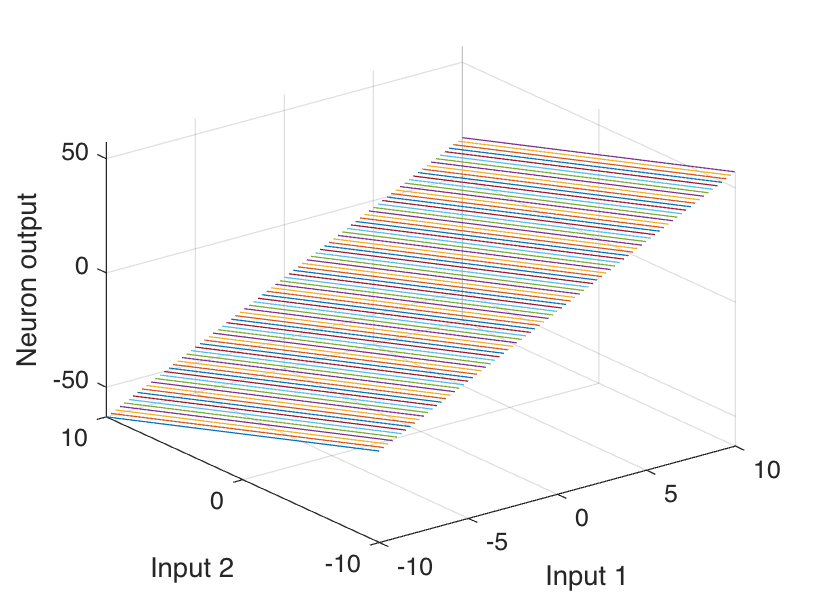

% >>>>>>>>>> PART 1: Defining weights, bias + f(x) <<<<<<<<
% we define the Neuron Weights 
w = [4 -2];
%Then the neuron bias 
b = -3; 
% the activation function which will be used 
sfunc = 'tansig';
% Activation function: Logistic sigmoid transfer function 
%func = 'logsig';
% Activation function: Hard-limit transfer function (threshold) 
%func = 'hardlim';
% Activation function: Linear transfer function 
%func = 'purelin';

% >>>>>>>>>> PART 2: Initiate Input vectors <<<<<<<<
%define input vectors 
p = [2 3];

% >>>>>>>>>> PART 3: Neuron Input and Output <<<<<<<<
% calculate the neuron output 
net_input = p*w'+b;
% passing it through the activation function 
neuron_output = feval(func, net_input);

% >>>>>>>>>> PART 4: Plotting <<<<<<<<
[p1,p2] = meshgrid(-10:.25:10);
z = feval(func, [p1(:) p2(:)]*w'+b ); z = reshape(z,length(p1),length(p2)); plot3(p1,p2,z);
grid on;
xlabel('Input 1');
ylabel('Input 2');
zlabel('Neuron output');


% >> Task 2 - 3 omitted because not useful 4 me
% >>>>>>>>>>>>>>>>>>>>> Task 4
close all, clear all  clc;
% number of samples of each class
N = 20;
% define inputs and outputs
offset = 5; % offset for second class
x = [randn(2,N) randn(2,N)+offset]; % inputs
y = [zeros(1,N) ones(1,N)]; % outputs
% Plot input samples with plotpv (Plot perceptron input/target vectors) figure(1)
plotpv(x,y);

%instantiate the perceptron 
net = perceptron;

%training the network
net = train(net, x,y);
%view(net);

%plotting the decision boundary 
figure(1)
plotpc(net.IW{1},net.b{1});


% >>>>>>>>>>>>>>>>>>>>> Task 5
% >>>>>. Task 5 
close all, clear all  clc
% number of samples of each class
K = 30;
% define classes
q = .6; % offset of classes
A = [rand(1,K)-q; rand(1,K)+q]; 
B = [rand(1,K)+q; rand(1,K)+q]; 
C = [rand(1,K)+q; rand(1,K)-q];
D = [rand(1,K)-q; rand(1,K)-q];
% plot classes
plot(A(1,:),A(2,:),'bs')
hold on
grid on
plot(B(1,:),B(2,:),'r+')
plot(C(1,:),C(2,:),'go')
plot(D(1,:),D(2,:),'m*')
% text labels for classes
text(.5-q,.5+2*q,'Class A')
text(.5+q,.5+2*q,'Class B')
text(.5+q,.5-2*q,'Class C')
text(.5-q,.5-2*q,'Class D')
% define output coding for classes. This coding is used for visualizations purposes.
a = [0 1]';
b = [1 1]';
c = [1 0]';
d = [0 0]';

% define inputs (combine samples from all four classes)
P = [A B C D];
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B)) repmat(c,1,length(C)) repmat(d,1,length(D))];
 % repmat: Replicate and tile an array 
plotpv(P,T);

% create the perceptron 
net = perceptron;
% To see the adaptation you need to look at the plot while the code is running
E = 1;
net.adaptParam.passes = 1;
linehandle = plotpc(net.IW{1},net.b{1});
n = 0;
while (sse(E) && n<1000)
% sse: Sum squared error or mae: mean absolute error
    n = n+1;
    [net,Y,E] = adapt(net,P,T);
    linehandle = plotpc(net.IW{1},net.b{1},linehandle);
    drawnow;
    pause(2); % 2 seconds pause
end
% show perceptron structure
view(net);

% For example, classify an input vector of [0.7; 1.2]
p = [0.7; 1.2]
y = net(p)
% compare response with output coding (a,b,c,d)

% >>>>> Task 5b
close all, clear all clc
% number of samples of each cluster
K = 100;
% offset of clusters
q = .6;
% define 2 groups of input data
A1 = [rand(1,K)-q; rand(1,K)+q]; B1 = [rand(1,K)+q; rand(1,K)+q]; C1 = [rand(1,K)+q; rand(1,K)-q]; D1 = [rand(1,K)-q; rand(1,K)-q]; A = [A1 C1];
B = [B1 D1];
% plot data
plot(A(1,:),A(2,:),'k+',B(1,:),B(2,:),'b*')
xlim([-2,3]);
ylim([-2,3]);
grid on
hold on

% coding (+1/0) for 2-class XOR problem
a = 0; b = 1;
% define inputs (combine samples from all two classes)
P = [A B];
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B))];
net = perceptron;
% To see the adaptation you need to look at the plot while the code is running
E = 1;
net.adaptParam.passes = 1;
linehandle = plotpc(net.IW{1},net.b{1});
n = 0;
while (sse(E) & n<20) % sse: Sum squared error or mae: mean absolute error
    n = n+1;
    [net,Y,E] = adapt(net,P,T);
    linehandle = plotpc(net.IW{1},net.b{1},linehandle); drawnow;
    pause(2); % 2 seconds pause
end
% show perceptron structure
view(net);

% >>>> Task 6a: XOR
close all, clear all clc
% number of samples of each cluster
K = 100;
% offset of clusters
q = .6;
% define 2 groups of input data
A1 = [rand(1,K)-q; rand(1,K)+q]; B1 = [rand(1,K)+q; rand(1,K)+q]; C1 = [rand(1,K)+q; rand(1,K)-q]; D1 = [rand(1,K)-q; rand(1,K)-q]; A = [A1 C1];
B = [B1 D1];
% plot data
plot(A(1,:),A(2,:),'k+',B(1,:),B(2,:),'b*')
grid on
hold on

% coding (+1/0) for 2-class XOR problem (plots will be more interpretable with codes 0/1 instead of [0 1]/[1/0])
a = 0;
b = 1;

% define inputs (combine samples from all two classes)
P = [A B];
  
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B))];

% create a neural network
% Input, output and output layers sizes are set to 0. These sizes will automatically be
% configured to match particular data by train
net = feedforwardnet([20]); % We create a network with one hidden layer of 20 neurons (try
%also with [5 3])
% look at the default parameters % ... mse, purelin, ...
%
net
% train the neural network
[net,tr,Y,E] = train(net,P,T);
% Notice that tr has the indices of the training, validation and test data sets: % tr.trainInd
% tr.valInd
% tr.testInd
% show network
view(net)
% Accuracy
fprintf('Accuracy: %f\n',100-100*sum(abs((Y>0.5)-T))/length(T))

figure(2)
plot(T','linewidth',2)
hold on
plot(Y','r--')
grid on
legend('Targets','Network response','location','best')
ylim([-1.25 1.25]);

% generate a grid
span = -1:.005:2;
[P1,P2] = meshgrid(span,span);
pp = [P1(:) P2(:)]';
% simulate neural network on a grid
aa = net(pp);
% plot classification regions
figure(1)
mesh(P1,P2,reshape(aa,length(span),length(span))-5);
colormap cool
view(2)
% show network
view(net);

% >>>>>> Task 6b: XOR 
close all, clear all clc
% number of samples of each cluster
K = 100;
% offset of clusters
q = .6;
% define 2 groups of input data
A1 = [rand(1,K)-q; rand(1,K)+q]; B1 = [rand(1,K)+q; rand(1,K)+q]; C1 = [rand(1,K)+q; rand(1,K)-q]; D1 = [rand(1,K)-q; rand(1,K)-q]; A = [A1 C1];
B = [B1 D1];
% plot data
plot(A(1,:),A(2,:),'k+',B(1,:),B(2,:),'b*')
grid on
hold on
% Define output coding
% coding (+1/0) for 2-class XOR problem
a = 0; b = 1;
% Prepare inputs and outputs for network training
% define inputs (combine samples from all two classes)
P = [A B];
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B))];
% create a neural network
net = feedforwardnet([20]);
% adjust the network for classification
for i =1:(length(net.layers)-1)
    %net.layers{i}.transferFcn = 'logsig'; % you can use either logsig or tansig
    net.layers{i}.transferFcn = 'tansig';
end
net.layers{end}.transferFcn = 'softmax';
% Cost function: crossentropy
net.performFcn = 'crossentropy';
% Train function: Gradient descent with momentum
net.trainFcn = 'traingdm'; net.trainParam.lr = 0.5; net.trainParam.mc = 0.8; net.trainParam.epochs = 2000;
% Train function: Scaled Conjugate Gradients. You can tried it instead of traingdm.
  
%net.trainFcn = 'trainscg'; net.trainParam.lr = 0.1; net.trainParam.mc = 0.8; %net.trainParam.epochs = 1000;
% The processFcns parameter is used when you want to perform certain preprocessing % steps on the network inputs and targets. Be careful, Matlab perform the most common % preprocessings automatically when you create a network. If you do not want any
% preprocessing you need to disable this parameter.
net.outputs{end}.processFcns = {};
% train the neural network
[net,tr,Y,E] = train(net,P,T);
% Notice that tr has the indices of the training, validation and test data sets: % tr.trainInd
% tr.valInd
% tr.testInd
% show network
view(net);
% Accuracy
fprintf('Accuracy: %f\n',100-100*sum(abs((Y>0.5)-T))/length(T))
% Plot targets and network response to see how good the network learns the data
figure(2)
plot(T','linewidth',2)
hold on
plot(Y','r--')
grid on
legend('Targets','Network response','location','best')
ylim([-1.25 1.25]);
% Plot classification result for the complete input space (separation by hyperplanes)
% generate a grid
span = -1:.005:2;
[P1,P2] = meshgrid(span,span);
pp = [P1(:) P2(:)]';
% simulate neural network on a grid
aa = net(pp);
% plot classification regions
figure(1);
mesh(P1,P2,reshape(aa,length(span),length(span))-5);
colormap cool
view(2);
% >>> Task 7 Custom Network
close all, clear all clc
inputs = [1:6]; % input vector (6-dimensional pattern); i.e. 1 2 3 4 5 6 
outputs = [7:12]; % corresponding target output vector; i.e. 7 8 9 10 11 12
% create the network: 1 input, 2 layer (1 hidden layer and 1 output layer), feed-forward network
net = network(1,2,[1; 0],[1; 0],[0 0; 1 0],[0 1]);
%We can then see the properties of sub-objects as follows:
net.inputs{1}
net.layers{1}, net.layers{2}
net.biases{1}
net.inputWeights{1}
net.layerWeights{2}
net.outputs{2}
%3) Define topology and transfer function
% number of hidden layer neurons
net.layers{1}.size = 5;
% hidden layer transfer function
net.layers{1}.transferFcn = 'logsig'; view(net);
%4) Configure the network
net = configure(net,inputs,outputs); view(net);
%5) Train net and calculate neuron output
% initial network response without training
initial_output = net(inputs)
%We can get the weight matrices and bias vector as follows:
net.IW{1}
net.LW{2}
net.b{1}
% network training
net.trainFcn = 'trainlm'; % trainlm: Levenberg-Marquardt backpropagation
% trainlm is often the fastest backpropagation algorithm in the toolbox, and is highly %recommended as a first choice supervised algorithm for regression, although it does %require more memory than other algorithms, as for example traingdm (Gradient descent %with momentum backpropagation) or traingdx (Gradient descent with momentum and %adaptive learning rate backpropagation).
% View network structure view(net);
net.performFcn = 'mse';
net = train(net,inputs,outputs);
net.IW{1}
net.LW{2}
net.b{1}

net(1) % For 1 as input the outputs should be close to 7 
net(2) % For 1 as input the outputs should be close to 8
net(3) % For 1 as input the outputs should be close to 9
net(4) % For 1 as input the outputs should be close to 10
net(5) % For 1 as input the outputs should be close to 11
net(6) % For 1 as input the outputs should be close to 12

view(net);